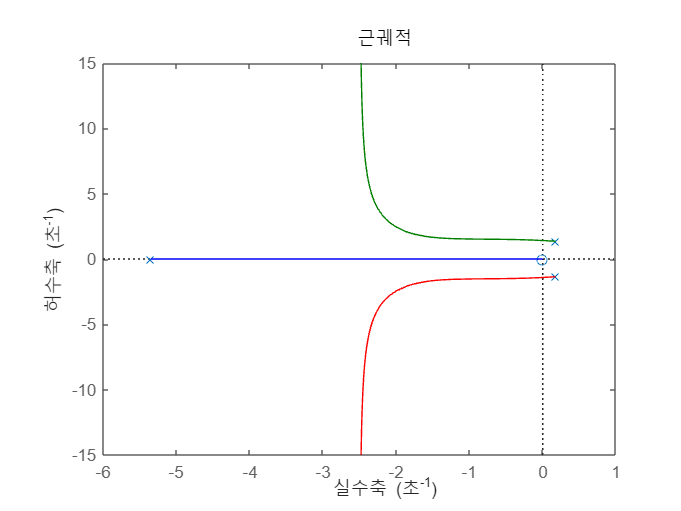

% E 7.21
clear all

syms s K omega a
assume(K,"positive");
assume(a,"positive");
assume(omega,"positive");
Ls = K*s/(s^3 + 5*s^2 + 10);
[n, d] = numden(Ls/K);
num = sym2poly(n);
den = sym2poly(d);
sys = tf(num, den);
figure();
rlocus(sys); % 근궤적



G = simplify(Ls/(1 + Ls));
zeta = 0.66;
[num1 den1] = numden(G);
eqn12 = simplify((s + a)*(s^2 + 2*zeta*omega*s + omega^2)) == den1

$$eqn12 = \left(a+s\right)\,\left(\omega^{2}+\frac{33\,\omega \,s}{25}+s^{2}\right)=s^{3}+5\,s^{2}+K\,s+10$$


eqn1 = a*omega^2 == 10

$$eqn1 = a\,\omega^{2}=10$$

eqn2 = 2*0.66*omega + a == 5

$$eqn2 = a+\frac{33\,\omega }{25}=5$$

sol = solve([eqn1 eqn2],[a omega]);
a = double(sol.a)           % 여기서 a값과 omega 값이 두 쌍이 나왔으므로 K값이 두개임을 예측할 수 있다.

a =     2.1595
    1.2185


omega = double(sol.omega)

omega =     2.1519
    2.8648



% K값은 두개이다. (진짜임 넣어서 K값 넣어서 zeta 구해보세요)   
for i = 1:size(a)
    a(i)*omega(i)^2;
    a(i)+2*0.66*omega(i);

    K1(i) = omega(i)^2 + 2*0.66*omega(i)*a(i);
end
K1

K1 =    10.7648   12.8148



% 각 K값이 zeta를 0.66으로 나오게 함을 확인하는 과정
for i = 1:2
    fprintf('K값이 %4.4f 일 때\n', K1(i))
    s = double(solve(subs(den1,K,K1(i)) == 0));
    for i = size(s,1):-1:1
        if abs(s(i)) == abs(real(s(i)))
            s(i) = []
        end
    end
    omega = sqrt(-s(1)*-s(2))
    zeta = (-s(1)-s(2))/(2*omega)
end

K값이 10.7648 일 때


s =   -1.4203 - 1.6167i
  -1.4203 + 1.6167i


omega = 2.1519

zeta = 0.6600

K값이 12.8148 일 때


s =   -1.8908 - 2.1522i
  -1.8908 + 2.1522i


omega = 2.8648

zeta = 0.6600